## Ερώτημα 1

% 1 -> Tails
% 0 -> Heads
clear variables; close all;
n = [10, 10^2, 10^3, 10^4, 10^5, 10^6, 10^7];
analogy = zeros(1, 7);
for ii = 1: length(n)
    res = flip_coin(n(ii));
    analogy(ii) = sum(res(:) == 1)/n(ii);
    fprintf('For %d flips, the analogy is %f \n', n(ii), analogy(ii))
end

For 10 flips, the analogy is 0.700000 
For 100 flips, the analogy is 0.530000 
For 1000 flips, the analogy is 0.489000 
For 10000 flips, the analogy is 0.505200 
For 100000 flips, the analogy is 0.500370 
For 1000000 flips, the analogy is 0.500526 
For 10000000 flips, the analogy is 0.499999 


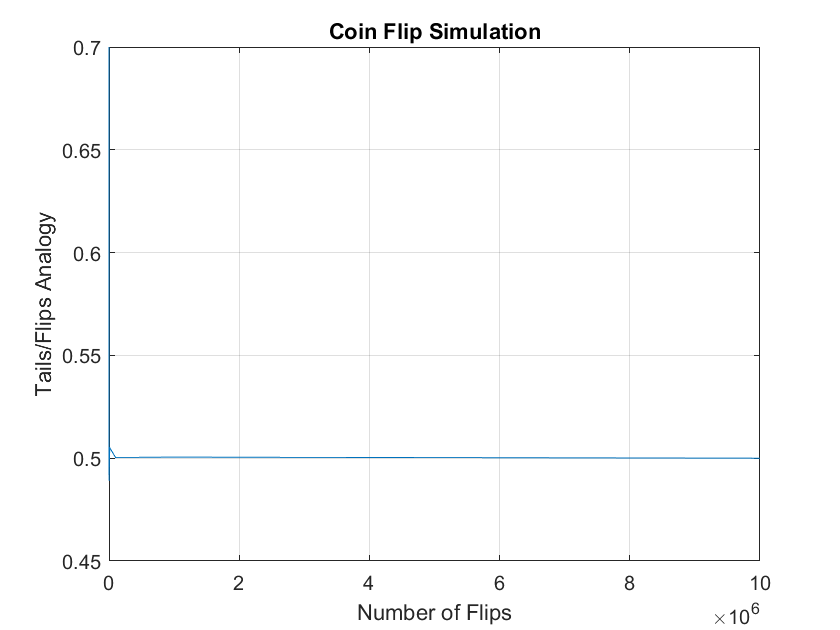


plot(n, analogy)
title('Coin Flip Simulation')
xlabel('Number of Flips')
ylabel('Tails/Flips Analogy')
grid('on')

## Ερώτημα 2

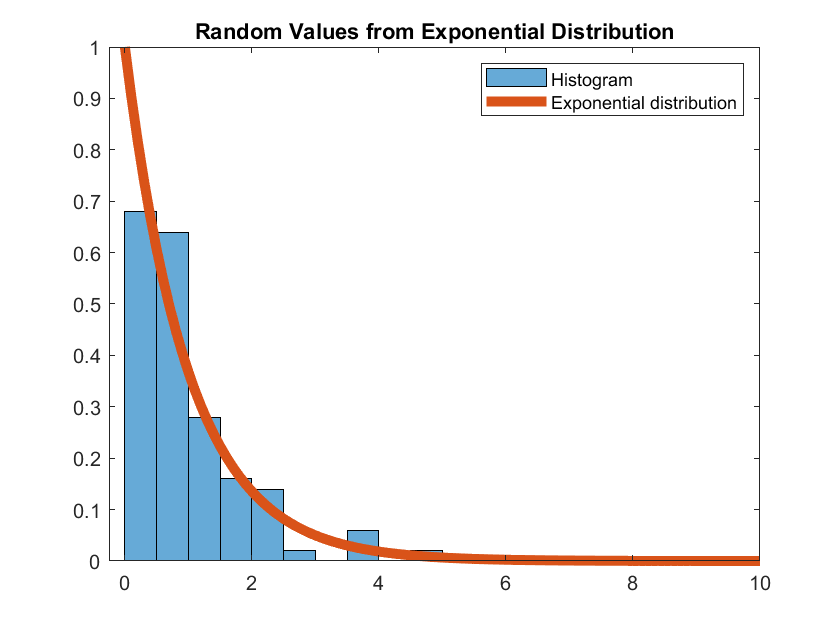

clear variables; close all;
x = 0:0.1:10;
f = exp(-x);    % f(x) = exp(-x)
unirand_values = rand(1, 100);
exprand_values = -log(unirand_values);  % f^-1 = -ln(x)
histogram(exprand_values,'Normalization','pdf')
hold on
title('Random Values from Exponential Distribution')
plot(x, f, 'Linewidth', 5)
legend('Histogram', 'Exponential distribution')

## Ερώτημα 3

mu = rand(1,2)

mu =     0.7277    0.5519


Sigma = [.9 .4; .4 .3];
r = mvnrnd(mu, Sigma, 10^6);
x = r(:, 1);
y = r(:, 2);
fprintf('Var(x+y) = %f \n', var(x+y))

Var(x+y) = 1.997414 


fprintf('Var(x) + Var(y) = %f', var(x) + var(y))

Var(x) + Var(y) = 1.198915

if abs(var(x) + var(y) - var(x+y)) < 0.01 
    fprintf('Var(x+y) = Var(x) + Var(y)')
else
    fprintf('Var(x+y) ~= Var(x) + Var(y)')
end

Var(x+y) ~= Var(x) + Var(y)